# **Numerical Differentiation **

## Example Problem

Estimate the velocity and acceleration from datasets of position of an object.

clear all

t = 0:0.2:4;
x = [-5.87 -4.23 -2.55 -0.89 0.67 2.09 3.31 4.31 5.06 5.55 5.78 5.77 5.52 5.08 4.46 3.72 2.88 2.00 1.10 0.23 -0.59];

A simple two-point differentiation can be used :

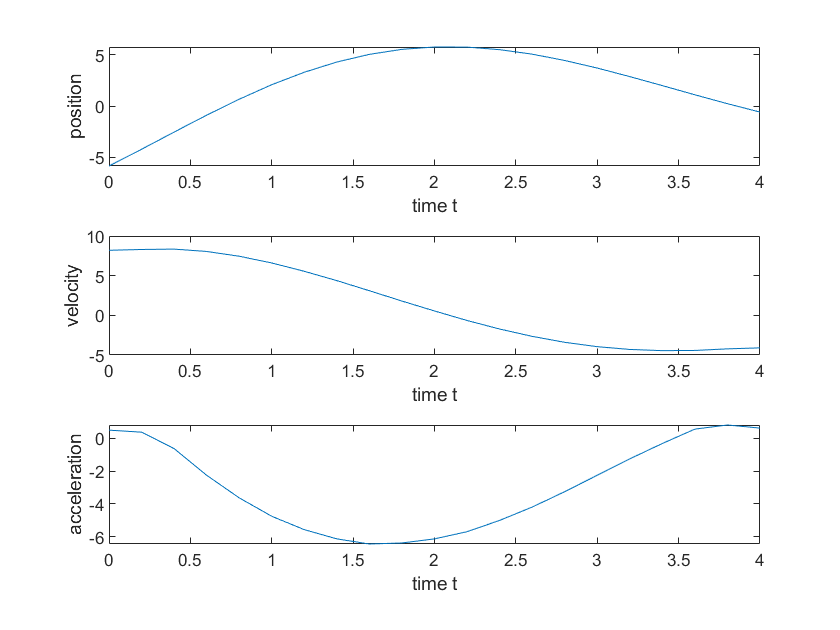

vel = derivative(t,x);
acc = derivative(t,vel);

figure
subplot (3,1,1)
    plot(t,x)
    xlabel('time t')
    ylabel('position')

subplot (3,1,2)
    plot(t,vel)
    xlabel('time t')
    ylabel('velocity')

subplot (3,1,3)
    plot(t,acc)
    xlabel('time t')
    ylabel('acceleration')

The function `derivative` can be designed simply as

function dx = derivative(x,y)
% The derivative: using two-point differentiation of  the central
% finite difference formula, except the first and the last data points. 

    n = length(x);
    dx(1)=(y(2)-y(1))/(x(2)-x(1));    
    for i=2:n-1
        dx(i)=(y(i+1)-y(i-1))/(x(i+1)-x(i-1));
    end    
    dx(n)=(y(n)-y(n-1))/(x(n)-x(n-1));
end